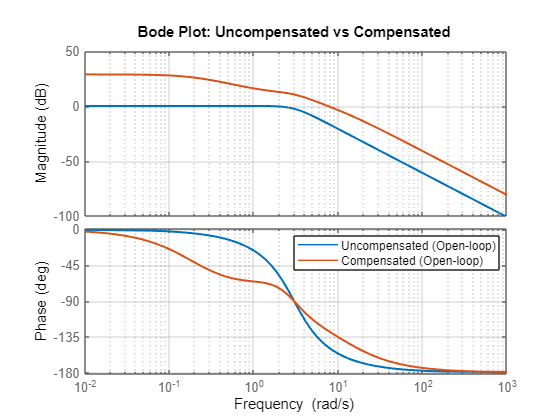

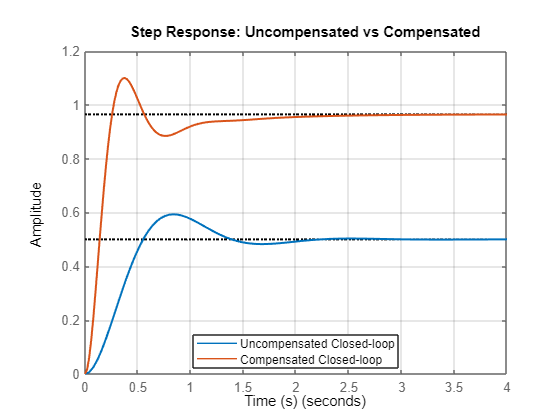

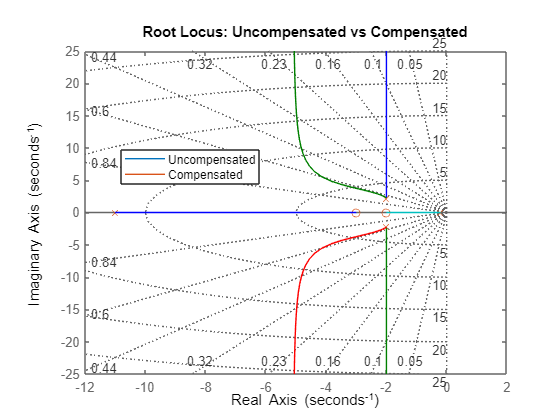

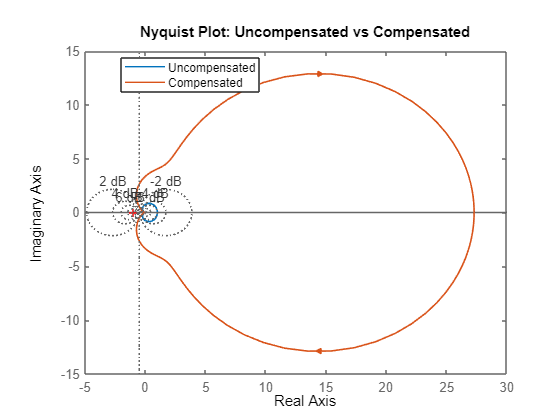


=== PERFORMANCE COMPARISON ===


Uncompensated System:


         RiseTime: 0.3735
    TransientTime: 1.9487
     SettlingTime: 1.9487
      SettlingMin: 0.4659
      SettlingMax: 0.5932
        Overshoot: 18.6319
       Undershoot: 0
             Peak: 0.5932
         PeakTime: 0.8289



Compensated System:


         RiseTime: 0.1746
    TransientTime: 1.5802
     SettlingTime: 1.5802
      SettlingMin: 0.8845
      SettlingMax: 1.0997
        Overshoot: 13.9976
       Undershoot: 0
             Peak: 1.0997
         PeakTime: 0.3759




Steady-State Error (Unit Step Input):


   Uncompensated: 9.0000


   Compensated:   9.0000



=== SYSTEM ANALYSIS SUMMARY ===


Lead compensator:     C_lead = 10*(s + 3)/(s + 11)


Lag compensator:      C_lag  = (s + 2)/(s + 0.2)


Combined compensator: C_T    = C_lead * C_lag



Performance Insights:


   -> Lead compensation improves speed of response (reduces rise & settling time).


   -> Lag compensation improves steady-state accuracy (reduces steady-state error).


   -> Combined lead-lag provides both transient and steady-state improvements.


%  NAME: Joshua Muthenya Wambua
%  REG NO: EG209/109705/22
%  DATE: 09-Nov-2025
%  Objective:
%     To design and analyze a lead–lag compensated control system
%     for improved transient and steady-state performance.
clc; clear; close all;

%  1. Define system and compensators
s = tf('s'); % Laplace variable
% Uncompensated second-order plant
G1 = 9 / (s^2 + 4*s + 9);
% Lead compensator (improves transient response)
C_lead = 10 * (s + 3) / (s + 11);
% Lag compensator (improves steady-state error)
C_lag = (s + 2) / (s + 0.2);
% Combined lead–lag compensator
C_T = C_lead * C_lag;
%  2. Closed-loop transfer functions
T_uncomp = feedback(G1, 1);           % Uncompensated closed-loop
T_comp   = feedback(C_T * G1, 1);     % Compensated closed-loop
%  3. Frequency Response Analysis
figure('Name','Bode Plot Comparison','NumberTitle','off');
bode(G1, C_T*G1);
grid on;
title('Bode Plot: Uncompensated vs Compensated');
legend('Uncompensated (Open-loop)', 'Compensated (Open-loop)', 'Location', 'best');
set(findall(gcf,'Type','line'),'LineWidth',1.5);
%  4. Step Response Analysis
figure('Name','Step Response Comparison','NumberTitle','off');
step(T_uncomp, T_comp, 4); % 4 seconds display window
grid on;
title('Step Response: Uncompensated vs Compensated');
legend('Uncompensated Closed-loop', 'Compensated Closed-loop', 'Location', 'best');
xlabel('Time (s)');
ylabel('Amplitude');
set(findall(gcf,'Type','line'),'LineWidth',1.5);
%  5. Root Locus & Nyquist Analysis
% Root Locus
figure('Name','Root Locus Comparison','NumberTitle','off');
rlocus(G1); hold on;
rlocus(C_T * G1);
grid on;
title('Root Locus: Uncompensated vs Compensated');
legend('Uncompensated', 'Compensated', 'Location', 'best');
% Nyquist Plot
figure('Name','Nyquist Plot Comparison','NumberTitle','off');
nyquist(G1, C_T*G1);
grid on;
title('Nyquist Plot: Uncompensated vs Compensated');
legend('Uncompensated', 'Compensated', 'Location', 'best');
set(findall(gcf,'Type','line'),'LineWidth',1.2);
%  6. Performance Metrics
fprintf('\n=== PERFORMANCE COMPARISON ===\n');
info_uncomp = stepinfo(T_uncomp);
info_comp   = stepinfo(T_comp);
disp('Uncompensated System:');
disp(info_uncomp);
disp('Compensated System:');
disp(info_comp);
% Compute steady-state error for a unit step
[~, ss_uncomp] = step(T_uncomp, 10);
[~, ss_comp]   = step(T_comp, 10);
ess_uncomp = abs(1 - ss_uncomp(end));
ess_comp   = abs(1 - ss_comp(end));
fprintf('\nSteady-State Error (Unit Step Input):\n');
fprintf('   Uncompensated: %.4f\n', ess_uncomp);
fprintf('   Compensated:   %.4f\n', ess_comp);
%  7. Summary Report (in Command Window)
fprintf('\n=== SYSTEM ANALYSIS SUMMARY ===\n');
fprintf('Lead compensator:     C_lead = 10*(s + 3)/(s + 11)\n');
fprintf('Lag compensator:      C_lag  = (s + 2)/(s + 0.2)\n');
fprintf('Combined compensator: C_T    = C_lead * C_lag\n');
fprintf('\nPerformance Insights:\n');
fprintf('   -> Lead compensation improves speed of response (reduces rise & settling time).\n');
fprintf('   -> Lag compensation improves steady-state accuracy (reduces steady-state error).\n');
fprintf('   -> Combined lead-lag provides both transient and steady-state improvements.\n');
fprintf('============================================================\n');

